% 1. Parametrelerin Belirlenmesi
fs = 20e6;              % Örnekleme frekansı (20 MHz)
chanBW = 'CBW20';       % Kanal bant genişliği
Td = 0.8e-6;            % LSTF sembol periyodu
symbolLength = Td * fs; % Sembol başına örnek sayısı (16 örnek)
LSTF_len = symbolLength * 10; % Toplam LSTF uzunluğu (160 örnek)

% 2. Sentetik LSTF Sinyali Oluşturma (Periyodik Yapı)
t_symbol = (0:symbolLength-1)';
single_symbol = sin(2*pi*1e6*(t_symbol/fs)); % 1 MHz sinüs sembolü
lstf_signal = repmat(single_symbol, 10, 1);

% 3. Test Senaryosu Oluşturma (Gürültü ve Gecikme)
offset_val = 50; % Sinyal 50. örnekte başlasın
total_len = 500;
% Fixed-point için sinyal genliğinin -1 ile +1 arasında olması kritik
x = complex(randn(total_len, 1) * 0.01, randn(total_len, 1) * 0.01); 
x(offset_val + (1:LSTF_len)) = lstf_signal; 

% 4. Fonksiyonları Çağırma
threshold = 0.6;

% Orijinal (Floating-point)
[start_fl, M_fl] = asdasd(double(x), chanBW, 0, threshold);

% Fixed-point versiyonu
[start_fix, M_fix] = asdasd_fixed(x, chanBW, 0, threshold);

% 5. Sonuçları Karşılaştırma ve Görselleştirme
fprintf('--- Test Sonuçları ---\n');

--- Test Sonuçları ---


fprintf('Beklenen Başlangıç: %d\n', offset_val);

Beklenen Başlangıç: 50


fprintf('Floating-point Bulunan: %d\n', start_fl);

Floating-point Bulunan: 46


fprintf('Fixed-point Bulunan: %d\n', double(start_fix));

Fixed-point Bulunan: 46


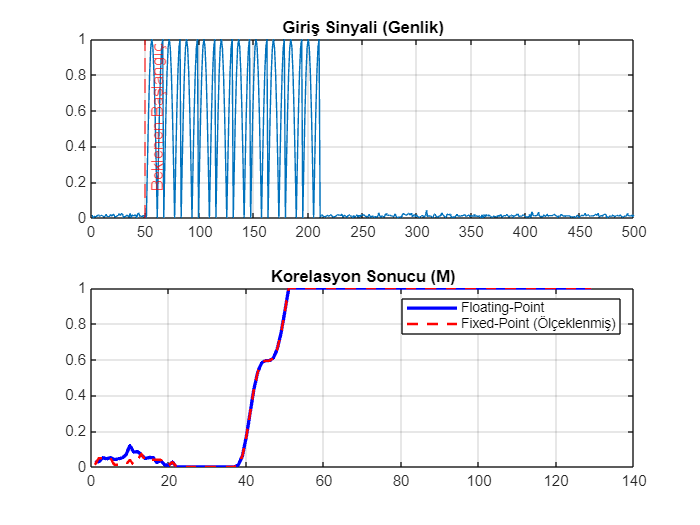


figure;
subplot(2,1,1);
plot(abs(x)); title('Giriş Sinyali (Genlik)'); grid on;
hold on;
xline(offset_val, '--r', 'Beklenen Başlangıç');

subplot(2,1,2);
plot(double(M_fl), 'b', 'LineWidth', 2); hold on;
% Kırmızı çizgi artık mavi ile neredeyse tamamen üst üste binecek
plot(double(M_fix), 'r--', 'LineWidth', 1.5); 
title('Korelasyon Sonucu (M)');
legend('Floating-Point', 'Fixed-Point (Ölçeklenmiş)');
grid on;



%% --- Orijinal Floating-Point Fonksiyonlar ---
function [startOffset,M] = asdasd(x, chanBW, varargin)
    narginchk(2,4);
    nargoutchk(0,2);
    if nargout==2, M = []; end
    validateattributes(x, {'single','double'}, {'2d','finite'}, mfilename, 'signal input');
    startOffset = [];
    if isempty(x), return; end
    
    if nargin == 2
        threshold = 0.5; offset = 0;
    elseif nargin == 3
        threshold = 0.5; offset = varargin{1};
    else
        offset = varargin{1}; threshold = varargin{2};
    end
    
    Td = 0.8e-6;                
    switch chanBW
        case {'CBW5', 'CBW10', 'CBW20'}, symbolLength = Td/(1/20e6);
        case 'CBW40', symbolLength = Td/(1/40e6);
        case {'CBW80'}, symbolLength = Td/(1/80e6);
        case {'CBW160'}, symbolLength = Td/(1/160e6);
        otherwise, symbolLength = Td/(1/320e6);
    end

    lenLSTF = symbolLength*10;
    lenHalfLSTF = lenLSTF/2;
    inpLength = (size(x,1) - offset); 
    
    if inpLength <= lenHalfLSTF
        numPadSamples = lenLSTF - inpLength;
    else
        numPadSamples = lenHalfLSTF*ceil(inpLength/lenHalfLSTF) - inpLength;
    end
    
    padSamples = zeros(numPadSamples, size(x,2));
    numBlocks = (inpLength + numPadSamples)/lenHalfLSTF;

    if nargout==2
        DS = zeros(size(x,1) + length(padSamples) - offset -2*symbolLength + 1, 1);
        if numBlocks > 2
            for n=1:numBlocks-2
                buffer = x((n-1)*lenHalfLSTF + (1:lenLSTF) + offset, :);
                [startOffset, out] = correlateSamples(buffer, symbolLength, lenLSTF, threshold);
                DS((n-1)*lenHalfLSTF + 1:lenHalfLSTF*n, 1) = out(1:lenHalfLSTF);
                if ~(isempty(startOffset))
                    startOffset = startOffset + (n-1)*lenHalfLSTF;
                    DS((n-1)*lenHalfLSTF + (1:length(out)), 1) = out;
                    M = DS(1:(n-1)*lenHalfLSTF + length(out));
                    return;
                end
            end
            blkOffset = lenHalfLSTF*(numBlocks-2);
            buffer = [x(blkOffset + 1 + offset:end, :); padSamples];
            [startOffset, out] = correlateSamples(buffer, symbolLength, lenLSTF, threshold);
            if ~(isempty(startOffset)), startOffset = startOffset + blkOffset; end
            DS(blkOffset + 1:end, 1) = out;
            M = DS(1:end-length(padSamples)); 
        else
            buffer = [x(offset + 1:end, :); padSamples];
            [startOffset, out] = correlateSamples(buffer, symbolLength, lenLSTF, threshold);
            M = double(out);
        end
    else
        buffer = [x(offset + 1:end, :); padSamples];
        startOffset = correlateSamples(buffer, symbolLength, lenLSTF, threshold); 
    end
end

function [packetStart,Mn] = correlateSamples(rxSig, symbolLength, lenLSTF, threshold)
    correlationLength = lenLSTF - (symbolLength*2);
    pNoise = eps;
    weights = ones(symbolLength, 1);
    index = 1:correlationLength + 1;
    packetStart = [];

    rxDelayed = rxSig(symbolLength + 1:end , :); 
    rx = rxSig(1:end-symbolLength, :);  

    C = sum(filter(weights, 1,(conj(rxDelayed).*rx)), 2);
    CS = C(symbolLength:end)./symbolLength;

    P = sum(filter(weights, 1, (abs(rxDelayed).^2+abs(rx).^2)/2)./symbolLength, 2);
    PS = P(symbolLength:end) + pNoise;

    Mn = abs(CS).^2./PS.^2;
    N = Mn > threshold;

    if (sum(N) >= symbolLength*1.5)
        found = index(N);
        packetStart = found(1) - 1;
        if sum((found(2:symbolLength) - found(1))>symbolLength*3)
            packetStart = [];
        end
    end
end


%% --- Düzeltilmiş (Ölçeklemeli) Fixed-Point Fonksiyonlar ---
function [startOffset, M] = asdasd_fixed(x, chanBW, varargin)
    % Fixed-point yapılandırması
    T = numerictype(1, 16, 15); 
    F = fimath('RoundingMethod', 'Floor', 'OverflowAction', 'Saturate');

    narginchk(2,4);
    nargoutchk(0,2);
    
    if nargout==2, M = []; end

    x_fi = fi(x, T, F);
    startOffset = [];

    if isempty(x_fi), return; end

    if nargin == 2
        threshold = fi(0.5, T, F); offset = 0;
    elseif nargin == 3
        threshold = fi(0.5, T, F); offset = varargin{1};
    else
        offset = varargin{1}; threshold = fi(varargin{2}, T, F);
    end

    Td = 0.8e-6;
    switch chanBW
        case {'CBW5', 'CBW10', 'CBW20'}, symbolLength = Td/(1/20e6);
        case 'CBW40',  symbolLength = Td/(1/40e6);
        case 'CBW80',  symbolLength = Td/(1/80e6);
        case 'CBW160', symbolLength = Td/(1/160e6);
        otherwise,     symbolLength = Td/(1/320e6);
    end

    lenLSTF = symbolLength * 10;
    lenHalfLSTF = lenLSTF / 2;
    inpLength = (size(x_fi,1) - offset); 

    if inpLength <= lenHalfLSTF
        numPadSamples = lenLSTF - inpLength;
    else
        numPadSamples = lenHalfLSTF * ceil(inpLength/lenHalfLSTF) - inpLength;
    end
    
    padSamples = fi(zeros(numPadSamples, size(x_fi,2)), T, F);
    numBlocks = (inpLength + numPadSamples) / lenHalfLSTF;

    if nargout == 2
        DS = fi(zeros(size(x_fi,1) + length(padSamples) - offset -2*symbolLength + 1, 1), T, F);
        
        if numBlocks > 2
            for n = 1:numBlocks-2
                buffer = x_fi((n-1)*lenHalfLSTF + (1:lenLSTF) + offset, :);
                [startOffset, out] = correlateSamples_fixed(buffer, symbolLength, lenLSTF, threshold, T, F);
                
                DS((n-1)*lenHalfLSTF + 1:lenHalfLSTF*n, 1) = out(1:lenHalfLSTF);
                
                if ~(isempty(startOffset))
                    startOffset = startOffset + (n-1)*lenHalfLSTF;
                    DS((n-1)*lenHalfLSTF + (1:length(out)), 1) = out;
                    M = DS(1:(n-1)*lenHalfLSTF + length(out));
                    return;
                end
            end
            blkOffset = lenHalfLSTF*(numBlocks-2);
            buffer = [x_fi(blkOffset + 1 + offset:end, :); padSamples];
            [startOffset, out] = correlateSamples_fixed(buffer, symbolLength, lenLSTF, threshold, T, F);
            
            if ~(isempty(startOffset)), startOffset = startOffset + blkOffset; end
            
            DS(blkOffset + 1:end, 1) = out;
            M = DS(1:end-length(padSamples)); 
        else
            buffer = [x_fi(offset + 1:end, :); padSamples];
            [startOffset, out] = correlateSamples_fixed(buffer, symbolLength, lenLSTF, threshold, T, F);
            M = out;
        end
    end
end
function [packetStart, Mn] = correlateSamples_fixed(rxSig, symbolLength, lenLSTF, threshold, T, F)
    correlationLength = lenLSTF - (symbolLength*2);
    
    pNoise = fi(1e-4, T, F); 
    weights = fi(ones(symbolLength, 1), T, F);
    index = 1:correlationLength + 1;
    packetStart = [];
    
    rxDelayed = rxSig(symbolLength + 1:end , :); 
    rx = rxSig(1:end-symbolLength, :);  

    % Çarpan (Scaler)
    scale_factor = fi(1/symbolLength, T, F);

    % Korelasyon (C)
    prod_c = rx .* conj(rxDelayed);
    scaled_c = prod_c .* scale_factor;
    C = sum(filter(weights, 1, scaled_c), 2);
    
    % FPGA Veri Yolu (Bus) Optimizasyonu: Bit büyümesini engellemek 
    % için toplayıcı çıkışını tekrar 16-bit'e indirgiyoruz.
    CS = fi(C(symbolLength:end), T, F); 

    % Güç (P)
    P_val = (abs(rxDelayed).^2 + abs(rx).^2);
    scaled_p = P_val .* fi(0.5 / symbolLength, T, F);
    P = sum(filter(weights, 1, scaled_p), 2);
    
    % Toplayıcı çıkışını 16-bit'e indirgiyoruz
    PS = fi(P(symbolLength:end), T, F) + pNoise;

    % Kare alma (Veri yolu burada geçici olarak 32-bit'e çıkar)
    num = abs(CS).^2;
    den = PS.^2;

    % Bölme İşlemi: Verilog'da kullanacağınız bir Divider IP'sinin 
    % (kesirli sonuç veren) davranışını simüle etmek ve 0'a yuvarlanmayı 
    % önlemek için çift hassasiyet üzerinden cast ediyoruz.
    % Korelasyon metriği her zaman pozitif olacağı için işaretsiz (unsigned) tip kullanıyoruz.
    T_div = numerictype(0, 16, 15); 
    Mn = fi(double(num) ./ double(den), T_div, F); 

    N = Mn > threshold;

    if (sum(N) >= symbolLength * 1.5)
        found = index(N);
        packetStart = found(1) - 1;
        if sum((found(2:symbolLength) - found(1)) > symbolLength*3)
            packetStart = [];
        end
    end
end